clear;
x=-1:0.2:1;
y=1./(1+25.*x.*x);
data=[x' y'];

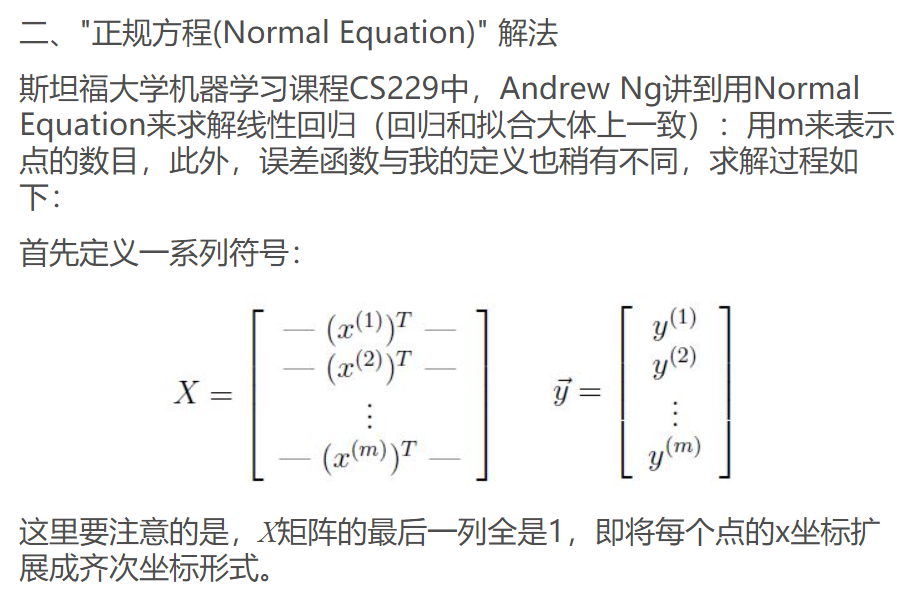

现在开始按照这个实现

比如输入x出y

方程为ax4+bx3+cx2+...+1=y

x第一项[a,b,c,d,e

%创建A
A=zeros(length(x),5);
for i_index=1:length(x)
    for j_index=1:5
        A(i_index,j_index)=x(i_index)^(5-j_index);
    end
end

b=y'

b =     0.0385
    0.0588
    0.1000
    0.2000
    0.5000
    1.0000
    0.5000
    0.2000
    0.1000
    0.0588


coef=(inv(A'*A))*A'*b

coef =     1.4852
   -0.0000
   -2.0604
    0.0000
    0.6552
